% restoredefaultpath
addpath C:\Users\User\Cloud-Drive\BigFiles\libs\fieldtrip-20230223
ft_defaults
addpath C:\Users\User\Cloud-Drive\BigFiles\libs\eeglab2023.0
addpath 'C:\Users\User\Cloud-Drive\BigFiles\libs'
addpath 'C:\Users\User\OneDrive\Documents\githubProjects\PE_Omission-Anat\ft_ERPAnalysis'

args = {};
args.subs = {'08','09','10','11','13','14','15','16','17','19','20','21','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'}; % add 23 to night ones
args.ft_cond_dir= sprintf('C:\\Users\\User\\Cloud-Drive\\BigFiles\\OmissionExpOutput\\ft_erpAnalysis\\data_in_ft_cond_fomat');
args.bl = 100;
args.contrasts = {{'OFFirst5','ORFirst5'}};
args.pre_vs_post_conds_names = {'OR','OEf5'};
args.output_main_dir = sprintf('C:\\Users\\User\\Cloud-Drive\\BigFiles\\OmissionExpOutput\\ft_erpAnalysis\\spatiotemp_clusterPerm');

args.wake_files_name_suffix = 'wake_morning_referenced'; %wake_morning_referenced, wake_night_referenced, wake_all_referenced

subs = args.subs;
wake_files_name_suffix = args.wake_files_name_suffix;
ft_cond_dir = args.ft_cond_dir;
bl = args.bl;
contrasts = args.contrasts;
pre_vs_post_conds_names = args.pre_vs_post_conds_names;
output_main_dir = args.output_main_dir;
%%%%%%%%%%%%%%%%%%%%%%%%%%
cond_rand_name ='OR';
imp = ft_importer(subs,ft_cond_dir,bl,wake_files_name_suffix);
timelock_OR = imp.get_cond_timelocked(imp,cond_rand_name);
electrodes = timelock_OR{1}.label;
time = timelock_OR{1}.time;
time0_ind = find(time == 0, 1);
time_from0 = time(time0_ind:end);
f = funcs_spatioTemporalAnalysis(imp, electrodes,time);

cond1_Vs_cond2_dir = sprintf('%s\\%s\\cond1_Vs_cond2',output_main_dir,wake_files_name_suffix);
pre_vs_poststim_dir = sprintf("%s\\%s\\preStim_Vs_postStim",output_main_dir,wake_files_name_suffix);
dir_baseline_erp = sprintf('%s\\%s\\baseline_erp',output_main_dir,wake_files_name_suffix);
persub_output_dir = sprintf("%s\\%s\\per_sub_electrode",output_main_dir,wake_files_name_suffix);
mkdir(cond1_Vs_cond2_dir);

mkdir(pre_vs_poststim_dir);

mkdir(dir_baseline_erp);

mkdir(persub_output_dir);


grandavg_cond1 = imp.get_cond_grandAvg(imp,'OF');

the call to "ft_selectdata" took 0 seconds
computing average of avg across 27 subjects
the call to "ft_timelockgrandaverage" took 0 seconds


grandavg_cond2 = imp.get_cond_grandAvg(imp,'OR');

the call to "ft_selectdata" took 0 seconds
computing average of avg across 27 subjects
the call to "ft_timelockgrandaverage" took 0 seconds


grandavg_cond3 = imp.get_cond_grandAvg(imp,'T');

the call to "ft_selectdata" took 0 seconds
computing average of avg across 27 subjects
the call to "ft_timelockgrandaverage" took 0 seconds


%grandavg_cond4 = imp.get_cond_grandAvg(imp,'A');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
cfg = [];
cfg.showlabels  = 'yes';
cfg.interactive  = 'no';

figure; ft_multiplotER(cfg,grandavg_cond1,grandavg_cond2)

the call to "ft_selectdata" took 0 seconds
creating layout from data.elec
creating layout for eeg system
the call to "ft_prepare_layout" took 1 seconds
the call to "ft_multiplotER" took 3 seconds


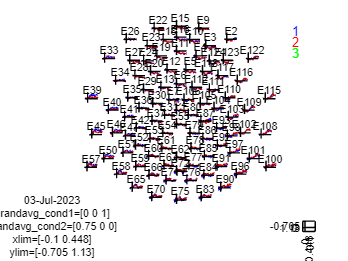

%blue - 1, red -2, green -3, purple - 4
text(0.5,0.35,'1','color','b') ;
text(0.5,0.3,'2','color','r');
text(0.5,0.25,'3','color','g');

%text(0.5,0.2,'4','color','black');


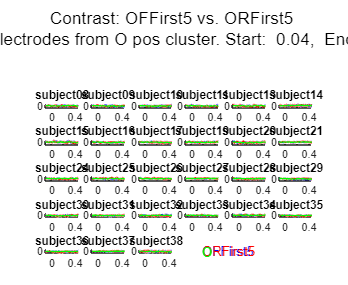

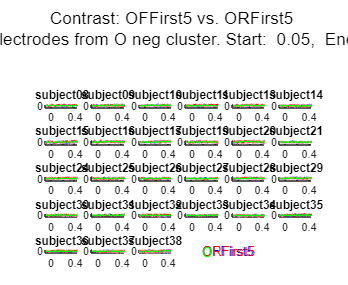

%% Plot erp of difference conditions per subject - for area
% central_electrodes = [6,25,61,80,93];
% frontal_electrodes = [8,9,13,14]; % E10, E11, E18, E16
% parital_electrodes = [48,49,52,58,59]; % E61, E62, E67, E77, E78
% temporalL_electrodes = [31,32,35] ;%E39, E40, E45

bl_cond_text = 'O';
for contrast_ind=1:size(args.contrasts,2)
    cond1_text = args.contrasts{contrast_ind}{1};
    cond2_text = args.contrasts{contrast_ind}{2};

    blCond_preVsPoststim = load(sprintf("%s\\preVsPoststim_bl-%d_%s_avg",pre_vs_poststim_dir, bl,bl_cond_text));
    
    for pos_neg_ind=1:2
        if pos_neg_ind ==1
            clusters = {blCond_preVsPoststim.posclusters.prob};
            clust_mask = blCond_preVsPoststim.posclusterslabelmat;
            title_text = sprintf("PreVsPoststim %s - positive clusters",bl_cond_text);
            pos_or_neg_text = 'pos';
        else
            clusters = {blCond_preVsPoststim.negclusters.prob};
            clust_mask = blCond_preVsPoststim.negclusterslabelmat;
            title_text = sprintf("PreVsPoststim %s - negative clusters",bl_cond_text);
            pos_or_neg_text = 'neg';
        end
        for clust_ind=1:size(clusters,2)
            curr_output_filename = sprintf("%s//clustCond-%s_contrast-%svs%s_bl-%d_clustInd-%d%s_PerSub.png",pre_vs_poststim_dir,bl_cond_text,cond1_text,cond2_text,bl,clust_ind,pos_or_neg_text);
            if isfile(curr_output_filename) continue; end
            if clusters{clust_ind} > 0.05   continue; end
            
            % get time-electrode mask for current cluster
            curr_clust_mask = clust_mask;
            curr_clust_mask(curr_clust_mask~=clust_ind) = 0;
            curr_clust_mask(curr_clust_mask ~= 0) = 1;
            temp = mean(curr_clust_mask,2);
            clust_electd = find(temp>0);
            temp = mean(curr_clust_mask,1);
            clust_times = find(temp>0);
    
            % Scaling of the vertical axis for the plots below
            grandavg_cond1 = imp.get_cond_timelocked(imp,cond1_text);
            grandavg_cond2 = imp.get_cond_timelocked(imp,cond2_text);
            grandavg_cond3 = imp.get_cond_timelocked(imp,bl_cond_text);
            % grandavg_cond4 = imp.get_cond_timelocked(imp,cond4);
            fig = figure('Position', [10 10 1100 900]);
            sgtitle(sprintf("Contrast: %s vs. %s \n Only electrodes from %s %s cluster. Start:  %.2f,  End:  %.2f\n",cond1_text,cond2_text,bl_cond_text,pos_or_neg_text,time(clust_times(1)),time(clust_times(end))));
            for isub = 1:size(subs,2)
                subplot(5,6,isub)
                hold on;
                
                y1 = grandavg_cond1{isub}.avg(clust_electd,:);
                y2 = grandavg_cond2{isub}.avg(clust_electd,:);
                y3 = mean(grandavg_cond3{isub}.avg(clust_electd,:),1);
                x = grandavg_cond1{isub}.time;
                shadedErrorBar(x,y1,{@mean,@std},'lineprops','-b','patchSaturation',0.2); 
                shadedErrorBar(x,y2,{@mean,@std},'lineprops','-r','patchSaturation',0.2); 
                plot(grandavg_cond1{isub}.time,y3, 'g');

                title(strcat('subject ',subs{isub}))
                 ylim([-2 2])
                 xlim([-0.1 0.45])
            end
            subplot(5,6,size(subs,2)+1);
            axis off
            text(0.5,0.7,cond1_text,'Color','b')
            text(0.5,0.5,cond2_text,'Color','r')
            text(0.5,0.2,'O','Color','g')
            saveas(fig, curr_output_filename)
        end
    end
end

%% check if there is any subject with O in the 4th place

ref_input_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced';
set_per_cond_dir = 'C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\TimeAnalysis\referenced_per_cond';

subs = {'08','09','10','12','11','13','14','15','16','17','19','20','21','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};
preproc_stage = 'referenced';

sleep_files_name_suffix = strcat('sleep_',preproc_stage);
wake_night_files_name_suffix = strcat('wake_night_',preproc_stage);
wake_morning_files_name_suffix = strcat('wake_morning_',preproc_stage);
suf_i = sleep_files_name_suffix;

for sub_ind=1:size(subs,2)
    set_file_input_name =   strcat('s_',subs(sub_ind),'_',suf_i,'.set');

    eeglabsub_eeg =  pop_loadset(set_file_input_name, ref_input_dir);
    events_type_arr = {eeglabsub_eeg.event.type};

    events_cond_i = find(contains(events_type_arr,'O') & contains(events_type_arr,'_4'));

    if ~isempty(events_cond_i)  
        subs{sub_ind}
    end
end

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_08_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_08_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_09_sleep_referenced.set ...
